clc;
clear;
close all;

Import file

[ping_received, Fs] = audioread('2khz10ms.wav');
dt = 1/Fs;

Select block of appropriate length as X using onset data. But here for analysis we use almost full signal

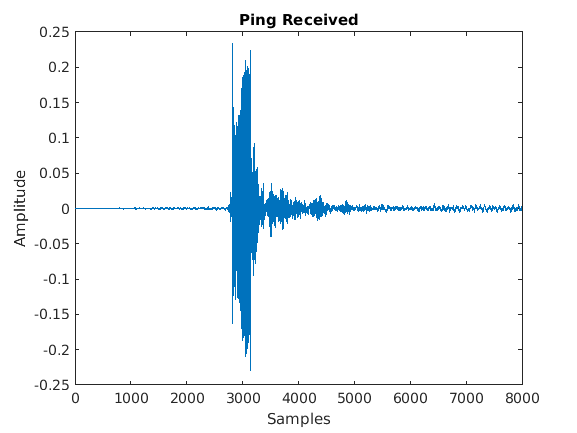

X = ping_received(1:8000);
plot(X)
title('Ping Received')
xlabel('Samples')
ylabel('Amplitude')

FFT for analysis

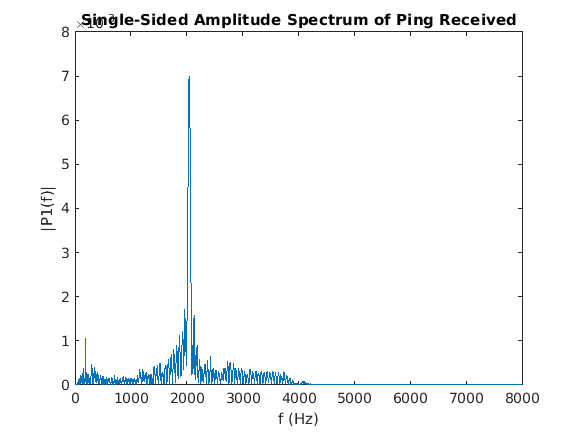

Y = fft(X);
L = length(X);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Ping Received')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Comb filter implementation, calibrated  for 2 kHz

notchspec = fdesign.comb('notch','N,Q',8,16,Fs);
peakspec = fdesign.comb('peak','N,Q',8,16,Fs);
notchfilt = design(notchspec,'SystemObject',true);
peakfilt = design(peakspec,'SystemObject',true);

Analysis of the comb filters using Filter Visualization Tool

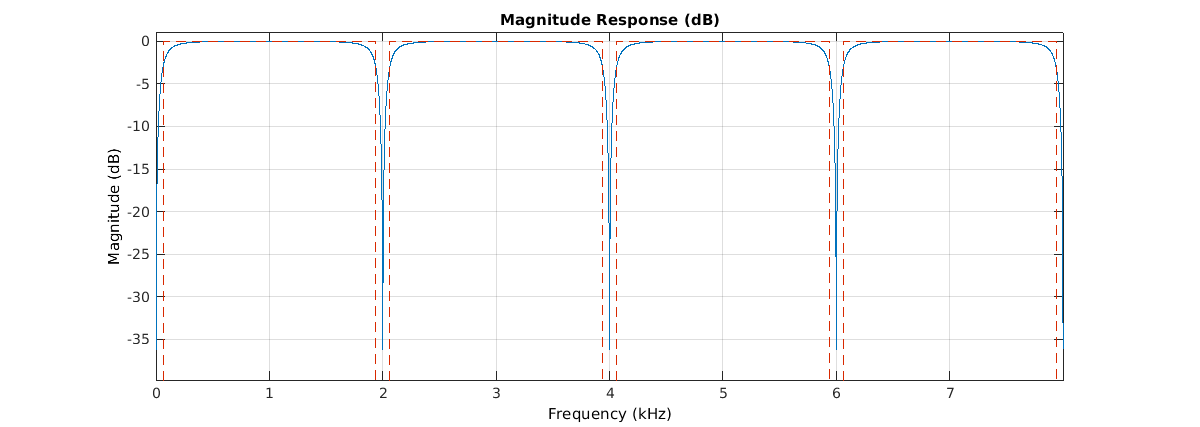

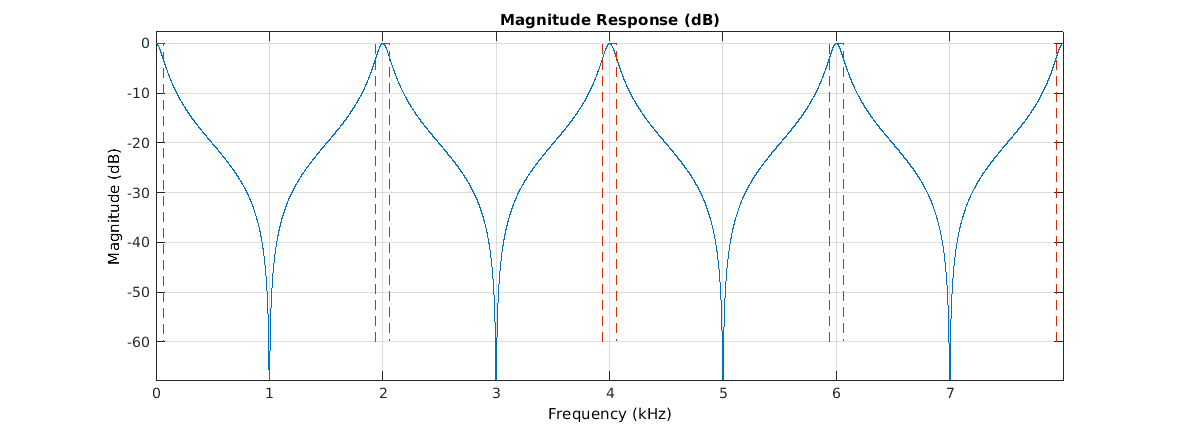

fvtool(notchfilt,'Color','white');
fvtool(peakfilt,'Color','white');

Filtering noisy signal through comb filter

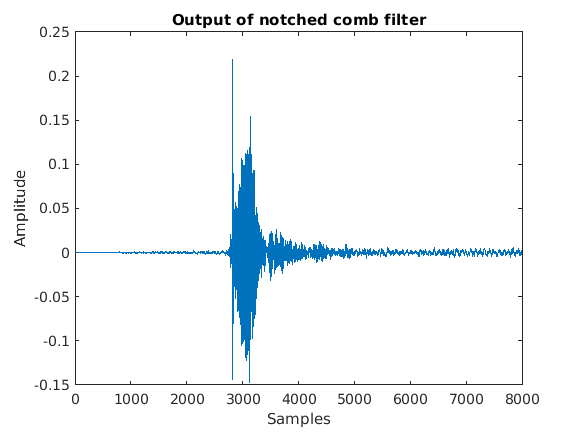

notched_opt = notchfilt(X);
peaked_opt = peakfilt(X);
plot(notched_opt)
title('Output of notched comb filter')
xlabel('Samples')
ylabel('Amplitude')

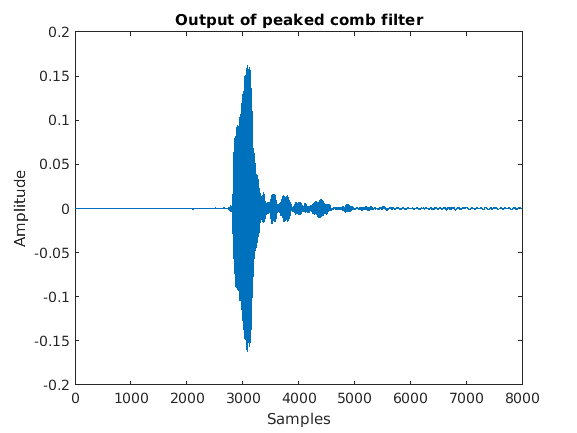

plot(peaked_opt)
title('Output of peaked comb filter')
xlabel('Samples')
ylabel('Amplitude')

Finding energy

peaked_energy = peaked_opt.^2;
notched_energy = notched_opt.^2;

Passing through given TF

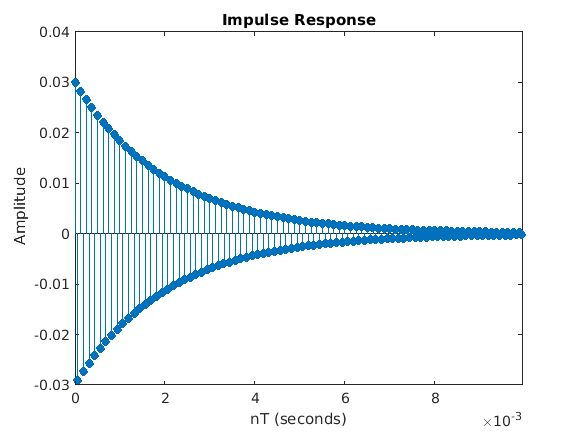

p=0.97;
Num1 = [(1-p) 0];
Den1 = [1 p];
sys = tf(Num1, Den1);
impz(Num1,Den1,160,Fs)


T = (L-1)*dt;
t = (0:dt:T);

peaked_opt = lsim(sys, peaked_energy,t);
notched_opt = lsim(sys, notched_energy,t);

Finding confidence

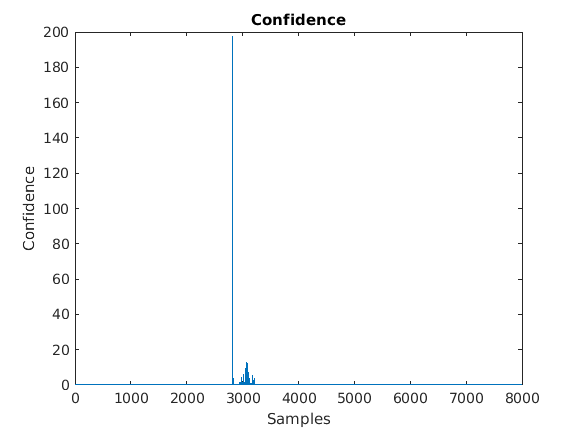

confidence = zeros([L,1]);
for i  = 1:1:L
    if(abs(peaked_opt(i,1)*notched_opt(i,1))>1.0e-08)
        confidence(i,1)=notched_opt(i,1)/peaked_opt(i,1);
    end
end
plot(confidence)
title('Confidence')
xlabel('Samples')
ylabel('Confidence')